# **IEC 61850 - 1 Client 2 Servers Loopback**

This example demonstrates how one IEC 61850 MMS Client and two IEC 61850 MMS Servers communicate using MMS, GOOSE and Sampled Values across two real-time target machines.

The IEC 61850 MMS Client station is on the first real-time target machine and the two IEC 61850 MMS Servers on the second real-time target machine. The two IEC 61850 MMS Servers are on the same Ethernet interface. This is achieved by assigning multiple alias-IP addresses to one Ethernet interface.

With this setup, the IEC 61850 Client and Servers are on the same network. Server 1 provides measurement values from a sensor whereas server 2 controls a breaker through direct control.

The Simulink model features the IEC 61850 blocks from the [speedgoatlib_iec61850](https://www.speedgoat.com/help/slrt/page/io_main/refentry_iec61850_landing) library.

## Setup

### Prerequisites

You will require the following to run this example:

- Two Speedgoat real-time target machines each with at least one unused Ethernet interface

- "Runtime License File" for IEC 61850 Client (if purchased) and Server(s). Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

- Ethernet cable min. CAT 5

### Wiring of Target Machine

Connect both real-time target machines to the same Ethernet switch preferably on ETH1. Then connect your development computer to the two real-time target machines as shown in the Quick Start Guide. **Note:** The default host link IP is 192.168.7.5. Change the host link IP address on one of the target machines if you wish to connect to two different IP addresses.

### Ethernet Configuration of the Client and Servers

Use the **Speedgoat Ethernet Configuration Tool** to assign the IP address to one unused Ethernet interface (on-board or IO71x/IO79x) on the target machine. The communication between the client and the server(s) on the unused Ethernet interface is performed on the local network, which is defined below.

**Before you make any changes to your Ethernet interfaces, please ensure that you record your personal configuration settings!**

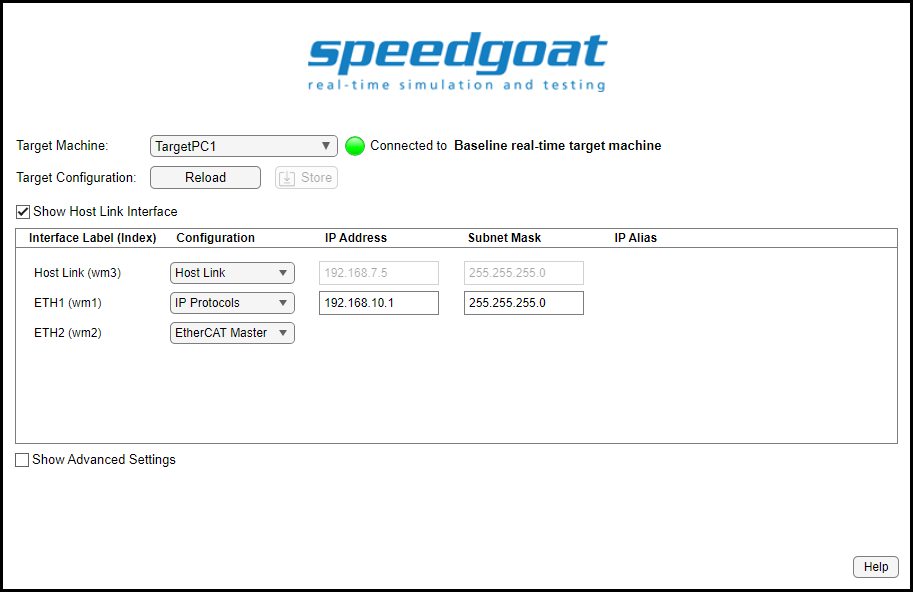

The IP address assigned on the first real-time target machine should be 192.168.10.1. The netmask for this address is 255.255.255.0. For the second real-time target machine, assign the IP address 192.168.10.2 and also use the same netmask as previously. These IPs are used as the gateway addresses for the client and server(s) in this example. 

**Note**: This is the ETH1 IP Address. The Host Link is the same as configured when connecting your target computer to the real-time target machine.

 
% To configure the Ethernet interface for the example use this command below to open the API
speedgoat.configureEthernet; % Do not mind the picture below, created after the execution of this command. There is no way to inhibit this output.

 
% Create target machine objects and connect to target machines
% and change the strings below to match your real-time target machine names
cli = slrealtime('TargetPC1'); 
srv = slrealtime('TargetPC2');
cli.connect
srv.connect

Add the IP addresses of the client and server(s) to the corresponding Ethernet interfaces. Adapt the name of the interface according to your machine configuration.

 
IP_Client_00 = '192.168.10.11';
IP_Server_01 = '192.168.10.21';
IP_Server_02 = '192.168.10.22';

InterfaceName = 'ETH1'; % Ethernet Interface on the target machine used for this example. Adapt this according to your machine.
ipAliasObj_cli = speedgoat.IpAliasConfiguration('TargetObject', cli);
ipAliasObj_cli.add(InterfaceName, {IP_Client_00});
ipAliasObj_srv = speedgoat.IpAliasConfiguration('TargetObject', srv);
ipAliasObj_srv.add(InterfaceName, {IP_Server_01, IP_Server_02});

Check the client and server Ethernet settings:

ipAliasObj_cli.show();
ipAliasObj_srv.show();

## Initialize and Open the Simulink Model

    
% Open the Simulink model
modelName = 'sgMdl_IEC61850_1CLI2SRV';
open_system(modelName);

## Configuring the MMS Servers

**Note***: *When using the configuration file parser, you **must have at least Java 8 Runtime** installed on your development computer. Java Runtime is not required when running the model, it is simply used to transform the CID files. To check if you have Java installed execute the following command:

java version "1.8.0_421" 
Java(TM) SE Runtime Environment (build 1.8.0_421-b09) 
Java HotSpot(TM) 64-Bit Server VM (build 25.421-b09, mixed mode) 


!java -version

The output should look similar to this:

When starting the model simulation, the [MMS Servers](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_iec61850_server) will search for a local data model configuration file based on the Station ID defined in the model. For configuring IEDs, the IEC standard defines multiple configuration files in the substation configration language (SCL).

There are two different configuration files located in the example folder. 

- The first one is an .icd (IED Capability Description) file. ICD files contain a description of the capabilities of a device. They are like templates that have a generic description of all the functions and objects that can be supported by a given device. The ICD is produced by the developer/manufacturer. 

- The second one is a .cid (Configured IED Description) file. An IED Configuration Tool (ICT) can use the IID(Instantiated IED Description) along with device-specific information (which could include mapping information) to create a Configured IED Description (CID) file which is used by the device to configure itself.

To configure the MMS Server Setup blocks, you must choose the CID file by clicking the **Send Config File to Target Machine**  button in the server Setup block mask. After choosing the file, select the real-time target machine. The file will then be stored locally on the machine. Repeat this step for all the Server Setup blocks.

 
speedgoat.model.highlight([modelName '/Bay/IEC 61850 MMS Server Measurement'], 'Open', true);
pause(2);
speedgoat.model.highlight([modelName '/Bay/IEC61850 MMS Server Direct Control'], 'Open', true);

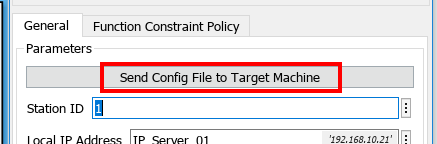

## Configuring the GOOSE and SV Subscribers

The GOOSE and Sampled Values Subscriber block masks have a button to read the local Interface MAC address of your real-time target machine.

A new window will open to select the real-time target machine. The MAC address from the Ethernet interface defined above is then read and directly written in the edit field below the button.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

**Note**: If no MMS Client runtime licenses have been purchased, the [MMS Client](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_iec61850_client) blocks must be commented to successfully run the example.

                     
% Build the Simulink model
slbuild([modelName, '/Corporate_Process'])
slbuild([modelName, '/Bay'])

 
% Reset the connection to the real-time target machines
% This helps to disconnect open connections
cli.reset;
srv.reset;

% Load the target applications into the real-time target machines
cli.load('Corporate_Process');
srv.load('Bay');

% Start the server and then the client with the given stop times
srv.setStopTime(25);
srv.start;
cli.setStopTime(24);
cli.start;

## Plot selected signals in SDI

 
% Clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2, 1); % layout with two plots
runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;

% Display all signals in the plot
for k = 4:6 % Select Signal index
    plotOnSubPlot(sigsobj(k), 1, 1, true);
end
Simulink.sdi.setSubplotLimits(1, 1, "yMin", -0.15, "yMax", 1.15);
for k = 9:11 % Select Signal index
    plotOnSubPlot(sigsobj(k), 2, 1, true);
end
Simulink.sdi.setSubplotLimits(2, 1, "yMin", -1.15, "yMax", 2.15);
Simulink.sdi.setSubplotLimits(2, 1, "tMin", 0, "tMax", 25);

% Open SDI
Simulink.sdi.view;

The output is then visible in the Simulink Data Inspector (SDI). You should see two subplots, as in the image below:

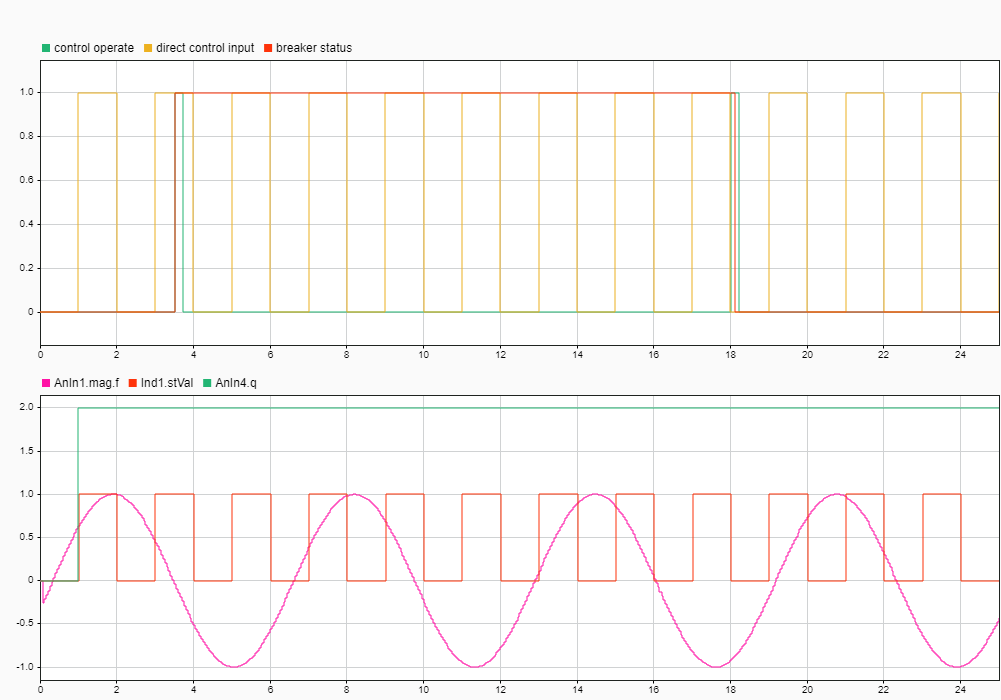

In the top subplot you can see the direct control signals. The **direct control** signal oscillates and its value is only transmitted when the **control operate** signal is 'high'. The switched stVal on the MMS server is then transmitted over GOOSE to the breaker.

The bottom subplot shows the attributes measured on the process level and transmitted via Sampled Values to the server and then read from the client via MMS. **AnIn1.mag.f** is the sine wave for a voltage measurement, **AnIn4.q** is the quality value which represents an uncertain status, and **Ind1.stVal** oscillates as a square wave.

## Restore Target Machine Configuration

To restore the default configuration, you can simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5 and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [IEC 61850 Client documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_iec61850_client)

- [IEC 61850 Server documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_iec61850_server)